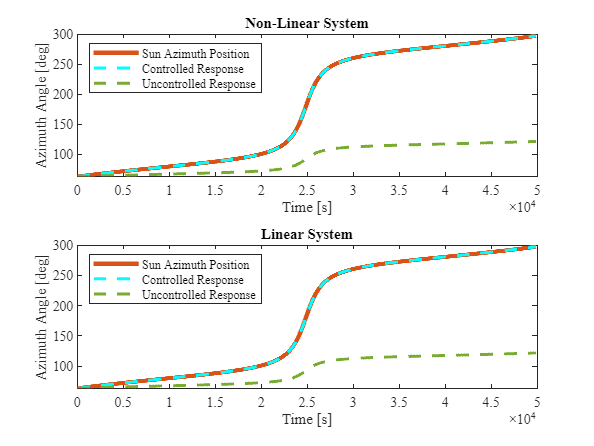

out1 = sim("Summer_Controlled.slx");
out2 = sim("Summer_Uncontrolled.slx");


Summer_Cont_data = out1.DecCont;

Summer_time = out1.DecCont.signals(1).values;
Summer_sundata = out1.DecCont.signals(2).values*180/pi;

Summer_Cont_nonlinear = out1.DecCont.signals(3).values*180/pi;
Summer_Cont_linear = out1.DecCont.signals(4).values*180/pi;

Summer_Uncont_data = out2.DecUncont;

Summer_Uncont_nonlincear = out2.DecUncont.signals(3).values*180/pi;
Summer_Uncont_linear = out2.DecUncont.signals(4).values*180/pi;



% plots Summer>Linear>Controller vs Uncontrolled
subplot(2,1,1);
plot(Summer_time,Summer_sundata,LineWidth=3,Color='#D95319')
hold on
plot(Summer_time,Summer_Cont_linear,LineWidth=2,LineStyle="--",Color='#00FFFF')
hold on
plot(Summer_time,Summer_Uncont_linear,LineWidth=2,LineStyle="--",Color='#77AC30')
legend('Sun Azimuth Position','Controlled Response','Uncontrolled Response','Location','northwest')
xlabel('Time [s]')
ylabel('Azimuth Angle [deg]')
title('Non-Linear System')
fontname('Times New Roman',11)
hold on


% plots Summer>Non-Linear>Controller vs Uncontrolled
subplot(2,1,2);
plot(Summer_time,Summer_sundata,LineWidth=3,Color='#D95319')
hold on
plot(Summer_time,Summer_Cont_nonlinear,LineWidth=2,LineStyle="--",Color='#00FFFF')
hold on
plot(Summer_time,Summer_Uncont_nonlincear,LineWidth=2,LineStyle="--",Color='#77AC30')
legend('Sun Azimuth Position','Controlled Response','Uncontrolled Response','Location','northwest')
title('Linear System')
xlabel({'Time [s]'; ''})
ylabel('Azimuth Angle [deg]')
fontname('Times New Roman',11)
hold off